# Методы реализации частотной модуляции

clear; close all;

## 1. VCO

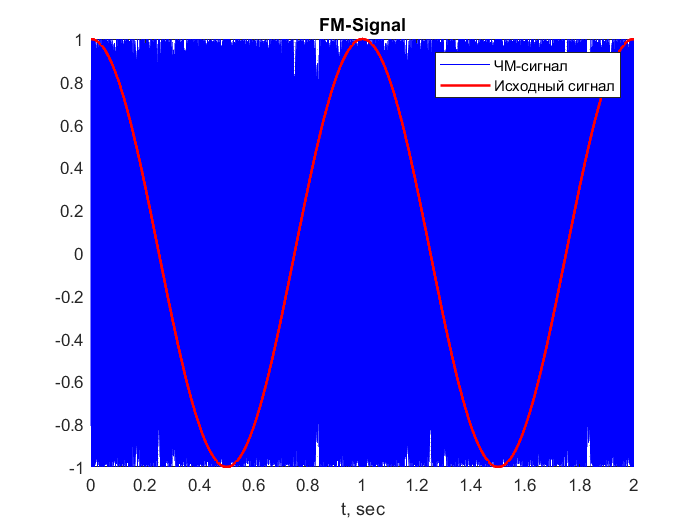

fs = 10e3;      % частота дискретизации
dt = 1/fs;      % период дискретизации
t  = 0:dt:2-dt; % отсчеты времени

% Различные информационные сигналы
x  = cos(2*pi*1*t);
% x  = square(2*pi*t,50);
% x  = sawtooth(2*pi*1*t);
% x  = 2*exp(-1.5*t)-1;
% x  = cos(2*pi*1*t)+cos(2*pi*3*t+pi/2);
x  = x/max(abs(x)); % нормировка

y  = vco(x,[0.1,0.3]*fs,fs); % формирование ЧМ-сигнала

plot(t,y,'-b'); grid on; grid minor;
line(t,x,'Color','Red','LineWidth',1.5);
xlabel('t, sec'); title('FM-Signal');
legend('ЧМ-сигнал','Исходный сигнал');

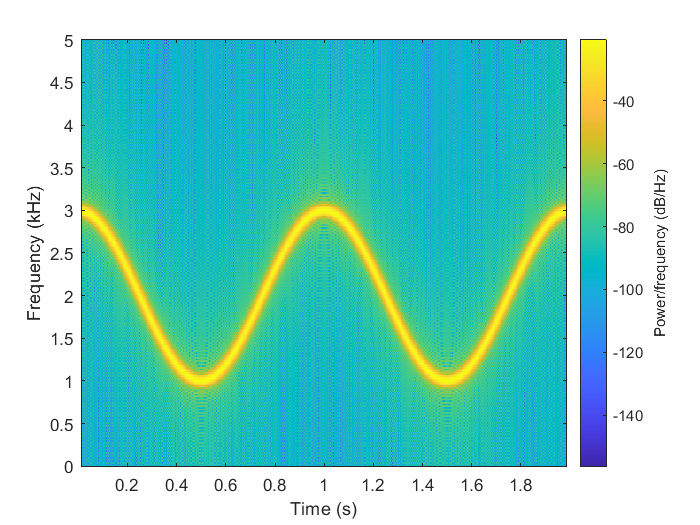


spectrogram(y,kaiser(256,5),220,512,fs,'yaxis');

## 2. FMMOD

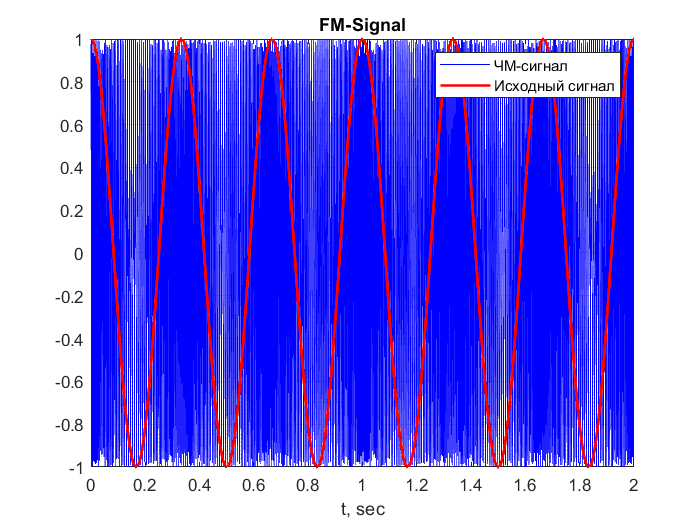

fc = 200;       % несущая частота
fs = 2e3;       % частота дискретизации
dt = 1/fs;      % период дискретизации
t  = 0:dt:2-dt; % отсчеты времени

% Различные информационные сигналы
x  = cos(2*pi*3*t);
% x  = cos(2*pi*1*t)+cos(2*pi*3*t+pi/2);

fDev = 70;                  % девиация частоты
y    = fmmod(x,fc,fs,fDev); % формирование ЧМ-сигнала

plot(t,y,'-b'); grid on; grid minor;
line(t,x,'Color','Red','LineWidth',1.5);
xlabel('t, sec'); title('FM-Signal');
legend('ЧМ-сигнал','Исходный сигнал');

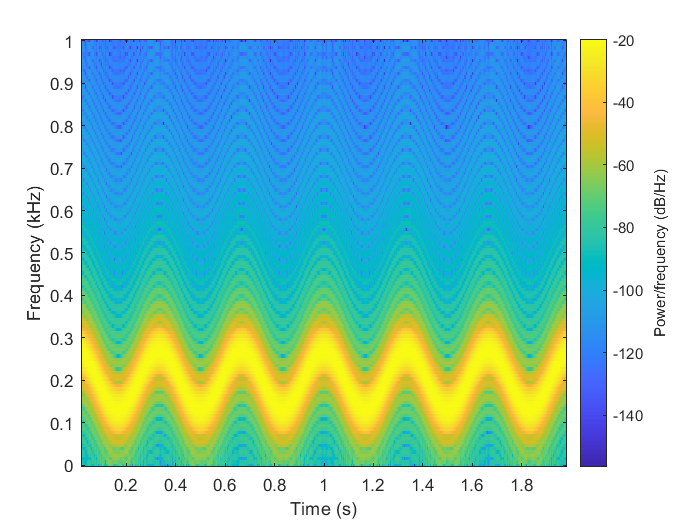


spectrogram(y,hann(64),63,[],fs,'yaxis');

## 3. CHIRP

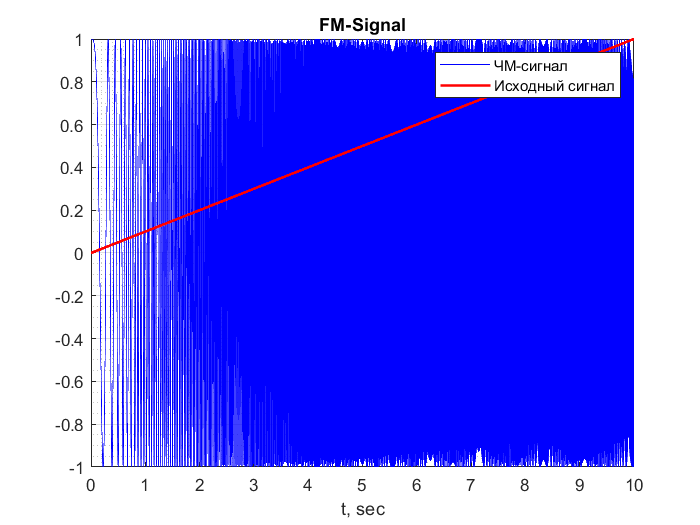

fs = 1e3;        % частота дискретизации
dt = 1/fs;       % период дискретизации
t  = 0:dt:10-dt; % отсчеты времени

f1 = 0;                 % начальная частота
f2 = 200;               % конечная частота
t2 = t(end);            % конечный отсчет
x  = (f2-f1)/t2*t+f1;   % исходный информационный сигнал
x  = x/max(x);
y  = chirp(t,f1,t2,f2); % формирование ЧМ-сигнала

plot(t,y,'-b'); grid on; grid minor;
line(t,x,'Color','Red','LineWidth',1.5);
xlabel('t, sec'); title('FM-Signal');
legend('ЧМ-сигнал','Исходный сигнал');

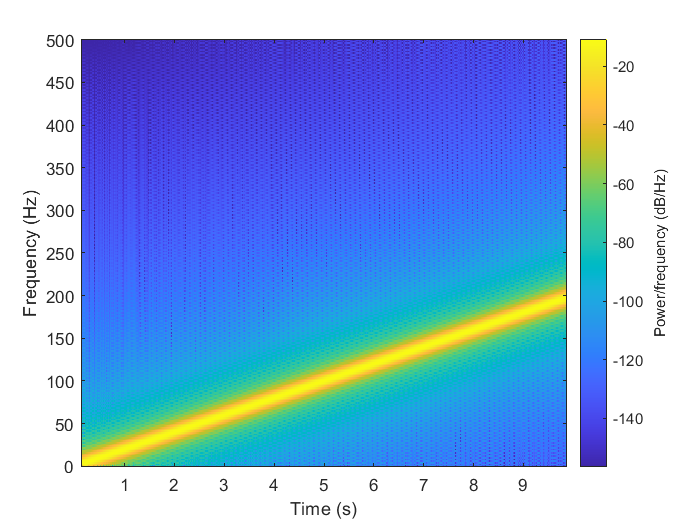


spectrogram(y,hann(256),250,512,fs,'yaxis');